% read wav files
[audio_1,rate_1]=audioread("./src/myaudio/audio1.wav");
[audio_2,rate_2]=audioread("./src/myaudio/audio2.wav");
[audio_3,rate_3]=audioread("./src/myaudio/audio3.wav");
[audio_4,rate_4]=audioread("./src/myaudio/audio4.wav");

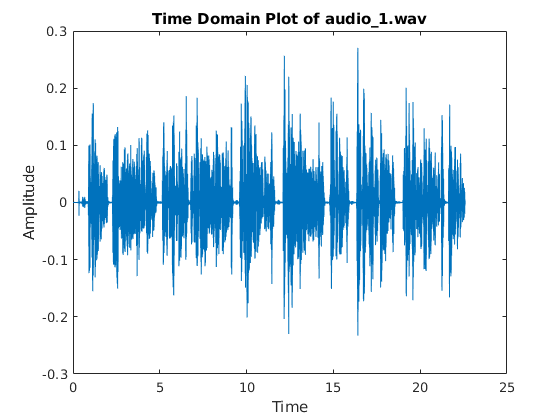

% time domain
% audio_1.wav
audio_vec=audio_1(:,1);
dt=1/rate_1;
t=0:dt:(length(audio_vec)*dt)-dt;
fig=plot(t,audio_vec);
title('Time Domain Plot of audio\_1.wav');
xlabel('Time');
ylabel('Amplitude');
saveas(fig,'./result/time_domain/audio_1.png');

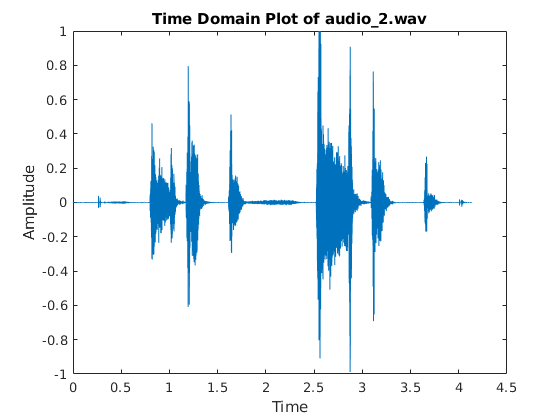

% audio_2.wav
audio_vec=audio_2(:,1);
dt=1/rate_2;
t=0:dt:(length(audio_vec)*dt)-dt;
fig=plot(t,audio_vec);
title('Time Domain Plot of audio\_2.wav');
xlabel('Time');
ylabel('Amplitude');
saveas(fig,'./result/time_domain/audio_2.png');

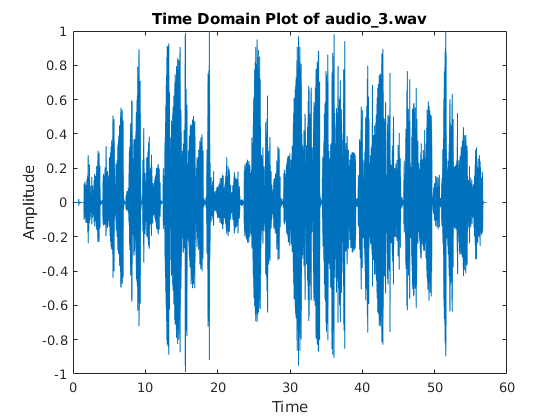

% audio_3.wav
audio_vec=audio_3(:,1);
dt=1/rate_3;
t=0:dt:(length(audio_vec)*dt)-dt;
fig=plot(t,audio_vec);
title('Time Domain Plot of audio\_3.wav');
xlabel('Time');
ylabel('Amplitude');
saveas(fig,'./result/time_domain/audio_3.png');

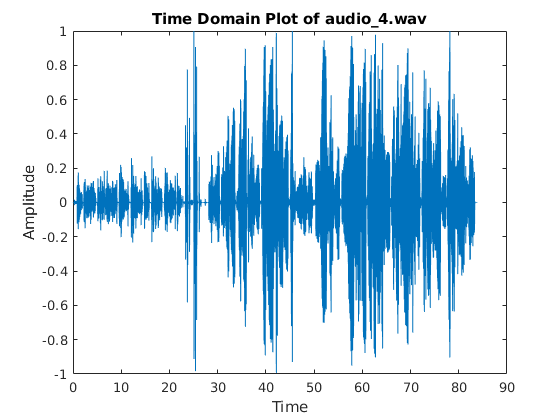

% audio_4.wav
audio_vec=audio_4(:,1);
dt=1/rate_4;
t=0:dt:(length(audio_vec)*dt)-dt;
fig=plot(t,audio_vec);
title('Time Domain Plot of audio\_4.wav');
xlabel('Time');
ylabel('Amplitude');
saveas(fig,'./result/time_domain/audio_4.png');

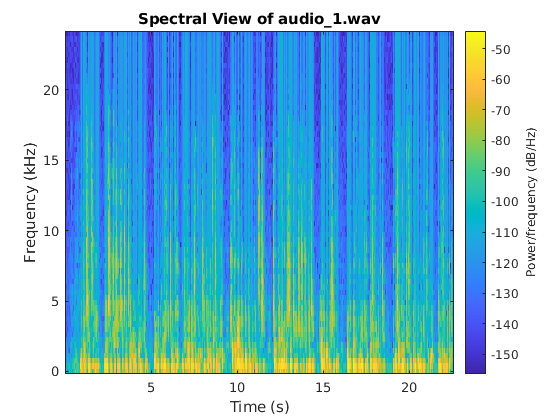

% spectral view
% audio_1.wav
audio_vec=audio_1(:,1);
win=128;
hop=win/2;
nfft=win;
spectrogram(audio_vec,win,hop,nfft,rate_1,'yaxis');
title("Spectral View of audio\_1.wav");
saveas(gcf,'./result/spectral_view/audio_1.png');

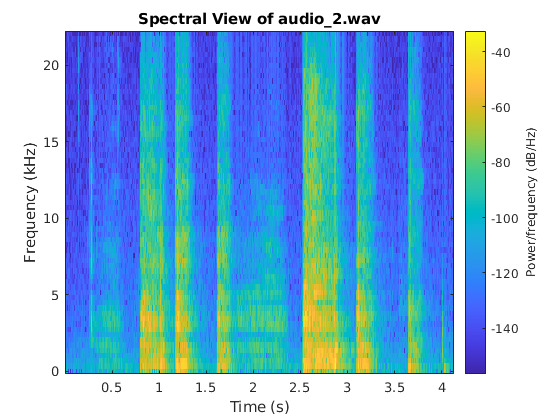

% audio_2.wav
audio_vec=audio_2(:,1);
win=128;
hop=win/2;
nfft=win;
spectrogram(audio_vec,win,hop,nfft,rate_2,'yaxis');
title("Spectral View of audio\_2.wav");
saveas(gcf,'./result/spectral_view/audio_2.png');

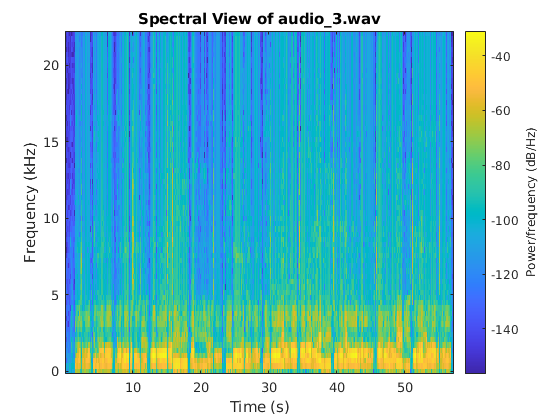

% audio_3.wav
audio_vec=audio_3(:,1);
win=128;
hop=win/2;
nfft=win;
spectrogram(audio_vec,win,hop,nfft,rate_3,'yaxis');
title("Spectral View of audio\_3.wav");
saveas(gcf,'./result/spectral_view/audio_3.png');

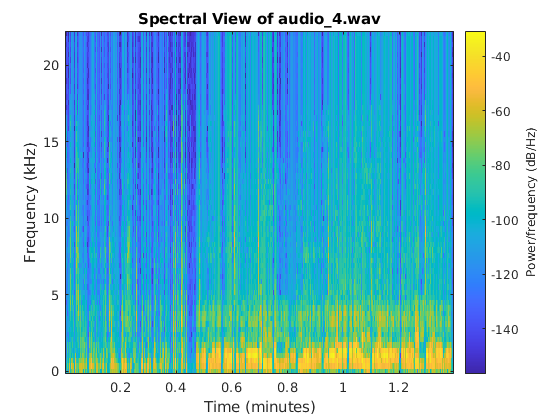

% audio_4.wav
audio_vec=audio_4(:,1);
win=128;
hop=win/2;
nfft=win;
spectrogram(audio_vec,win,hop,nfft,rate_4,'yaxis');
title("Spectral View of audio\_4.wav");
saveas(gcf,'./result/spectral_view/audio_4.png');

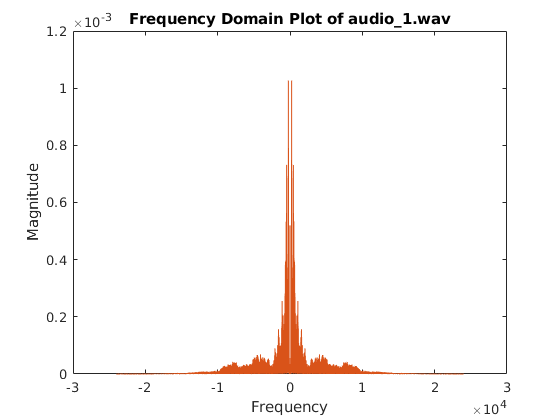

% frequency domain
% audio_1.wav
audio_length=length(audio_1);
df=rate_1/audio_length;
frequency_1=-rate_1/2:df:rate_1/2-df;
myaudio_fft_1=fftshift(fft(audio_1))/length(fft(audio_1));
plot(frequency_1,abs(myaudio_fft_1));
title('Frequency Domain Plot of audio\_1.wav');
xlabel('Frequency');
ylabel('Magnitude');
saveas(gcf,'./result/frequency_domain/audio_1.png');

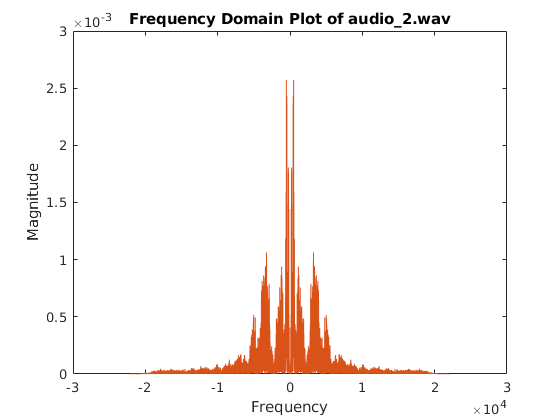

% audio_2.wav
audio_length=length(audio_2);
df=rate_2/audio_length;
frequency_2=-rate_2/2:df:rate_2/2-df;
myaudio_fft_2=fftshift(fft(audio_2))/length(fft(audio_2));
plot(frequency_2,abs(myaudio_fft_2));
title('Frequency Domain Plot of audio\_2.wav');
xlabel('Frequency');
ylabel('Magnitude');
saveas(gcf,'./result/frequency_domain/audio_2.png');

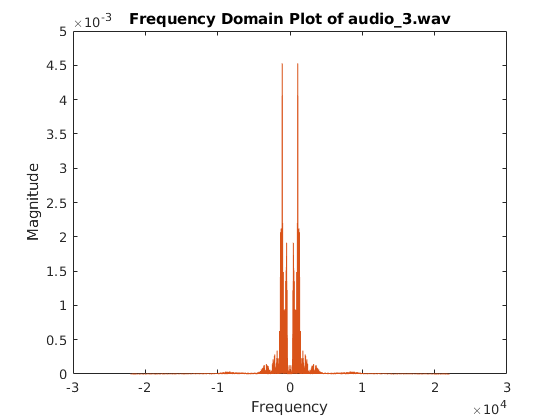

% audio_3.wav
audio_length=length(audio_3);
df=rate_3/audio_length;
frequency_3=-rate_3/2:df:rate_3/2-df;
myaudio_fft_3=fftshift(fft(audio_3))/length(fft(audio_3));
plot(frequency_3,abs(myaudio_fft_3));
title('Frequency Domain Plot of audio\_3.wav');
xlabel('Frequency');
ylabel('Magnitude');
saveas(gcf,'./result/frequency_domain/audio_3.png');

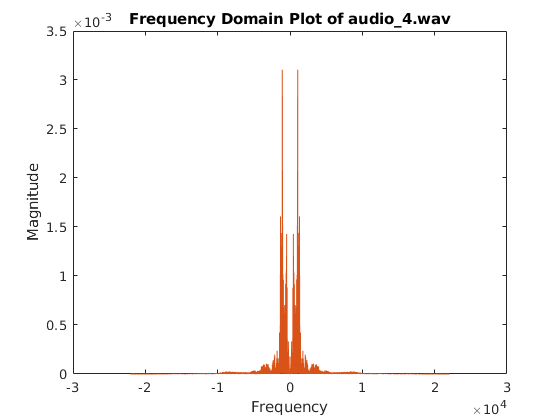

% audio_4.wav
audio_length=length(audio_4);
df=rate_4/audio_length;
frequency_4=-rate_4/2:df:rate_4/2-df;
myaudio_fft_4=fftshift(fft(audio_4))/length(fft(audio_4));
plot(frequency_4,abs(myaudio_fft_4));
title('Frequency Domain Plot of audio\_4.wav');
xlabel('Frequency');
ylabel('Magnitude');
saveas(gcf,'./result/frequency_domain/audio_4.png');

% Compare my audio with another girl
[sample_1,sample_rate_1]=audioread("./src/girl/speaking.wav");
[sample_2,sample_rate_2]=audioread("./src/girl/noise.wav");
[sample_3,sample_rate_3]=audioread("./src/girl/singing.wav");
[sample_4,sample_rate_4]=audioread("./src/girl/combination.wav");

% compare in spectral frequency domain
% speaking signal
audio_length=length(sample_1);
df=sample_rate_1/audio_length;
sample_frequency=-rate_1/2:df:rate_1/2-df;
sample_audio_fft=fftshift(fft(sample_1))/length(fft(sample_1));
disp(frequency_1(1));

      -24000



disp(sample_frequency(1));

      -24000



disp(frequency_1(length(frequency_1)));

   2.4000e+04



disp(sample_frequency(length(sample_frequency)));

   2.4000e+04



sample_points=-24000:1000:24000;
j=1;
my_magnitude=zeros(1,length(sample_points));
for i=1:length(frequency_1)
    if frequency_1(i)>=sample_points(j)
        my_magnitude(j)=abs(myaudio_fft_1(j,1));
        j=j+1;
    end
    if j==length(sample_points)
        break;
    end
end

j=1;
sample_magnitude=zeros(1,length(sample_points));
for i=1:length(sample_frequency)
    if sample_frequency(i)>=sample_points(j)
        sample_magnitude(j)=abs(sample_audio_fft(j,1));
        j=j+1;
    end
    if j==length(sample_points)
        break;
    end
end

my_magnitude=times(my_magnitude,10^8);
sample_magnitude=times(sample_magnitude,10^8);

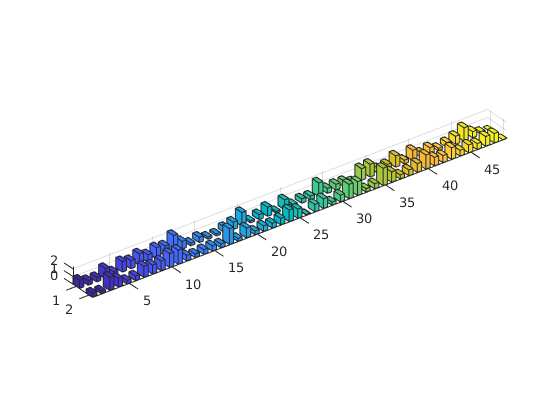

x=[my_magnitude(1,:);sample_magnitude(1,:)];
my_magnitude(1,1:20);
width=0.5;
bar3(x,width);

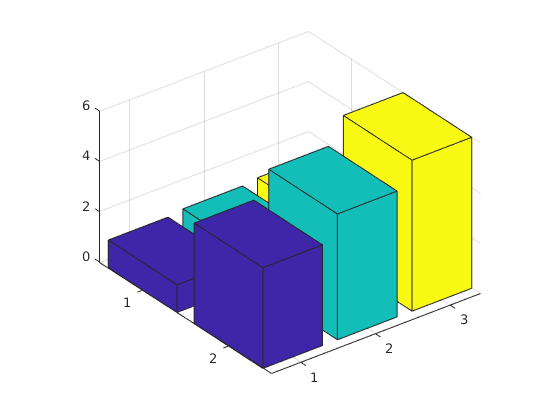

y=[1.1 1.2 1.3;4 5 6];
bar3(y);